clear

## Initialization

% configuration space
d=4; % dimension of the conf space
domain = [];
[X1,X2,X3,X4]=ndgrid([1,3,5,8,10,15,20,35,50,70,100,150,200,250,300,350,400,450,500,750,1000,1500,2000,3500,5000,7500,10000],[5,10,20,30,40,50,70,100,125,150,200,250,300,350,400,450,500,750,1000,1500,2000,3500,5000,7500,10000],[0:0.05:0.45],[0:0.05:0.45]);
xTest=[X4(:) X3(:) X2(:) X1(:)];

% these are different responses
yTest_mean_localization_error=csvread('../../experiments/cobot/mean_localization_error1.csv');
yTest_max_localization_error=csvread('../../experiments/cobot/max_localization_error1.csv');
yTest_mean_cpu=csvread('../../experiments/cobot/mean_cpu_percent1.csv');
yTest_wall_time=csvread('../../experiments/cobot/wall_time1.csv');

% select the response
yTest=yTest_mean_localization_error(:,2);
xTest=xTest(1:size(yTest,1),:);

% excluding invalid configurations
idx_valid=~(yTest_wall_time(:,2)==100);
xTest=xTest(idx_valid,:);
yTest=yTest(idx_valid,:);

% select the training set
idx_train=(xTest(:,1)==0 & xTest(:,2)==0);
xTrain=xTest(idx_train,:);
yTrain=yTest(idx_train,:);

idx_test=(xTest(:,1)==0.35 & xTest(:,2)==0.45);


%xTrainLimit=xTest(40500:end,:);
%yTrainLimit=yTest(40500:end,:);

%training_percent=1;
%numTrain=floor(size(xTest,1)*0.01*training_percent);

%n=size(xTrain,1);
%v=randperm(n);
%idx_train = v(1:numTrain);
%xTrain=xTrainLimit(idx_train,:);
%yTrain=yTrainLimit(idx_train,:);

## Training

## MTGP, transfer learning

initialize the prior

T=2; % number of tasks

gps = covMTKernelFactory(6,T,d)

gps =       per_hyp: 6
          ell: 1
           sf: 1
       cc_hyp: [1 0 1 0 0 1 0 0 0 1]
           sn: 0.1000
    noise_hyp: 1.0000e-03
     meanfunc: @meanConst
          hyp: [1×1 struct]
      covfunc: {'MTGP_covProd'  {1×2 cell}}
      likfunc: @likGauss


gps.hyp

ans =     mean: 0
     cov: [1 0 1 0 0 0 0 0]
     lik: -2.3026


% observations from other tasks
% n=size(xTest,1);
% v=randperm(n);
idx_source = idx_train;
X=xTest(idx_source,:);
%Y=yTest_wall_time(idx_mt_train,2);
ySource=yTest(idx_source,:)+randn*yTest(idx_source,:);
Y=ySource(idx_source,:);
observedX{2}=X;
observedY{2}=Y;

% v=randperm(n);
% idx_mt_train = v(1:size(idx_train,2));
% X=xTest(idx_mt_train,:);
% yTransferred=yTest_mean_localization_error(idx_valid,2)+rand*yTest_mean_localization_error(idx_valid,2);
% Y=yTransferred(idx_mt_train,:);
% observedX{3}=X;
% observedY{3}=Y;

target_size=2;
test_size=size(find(idx_test==1),1);
v=randperm(test_size);
idx_target=v(1:target_size);
xTarget=xTest(idx_test,:);
yTarget=yTest(idx_test,:);
% we only expect to receive small number of training on the target
xTarget=xTarget(idx_target,:);
yTarget=yTarget(idx_target,:);

% adding the training points on the target to the overal training data
%xTrain=[xTrain;xTarget];
%yTrain=[yTrain;yTarget];

observedX{1} = xTarget;
observedY{1} = yTarget;

x_test = [xTest ones(size(xTest,1),1)];
y_test = [yTest ones(size(xTest,1),1)];

x = [observedX{1}, ones(size(observedX{1},1),1)];
y = [observedY{1}];

for i_task = 2:T
    x = [x; observedX{i_task}, ones(size(observedX{i_task},1),1)*i_task];
    y = [y; observedY{i_task}];
    
    x_test=[x_test; xTest ones(size(xTest,1),1)*i_task];
    y_test=[y_test; yTest ones(size(yTest,1),1)*i_task];
end

% Bayesian model selection to find hyperparameter 
tic
gps = optmtHyp(gps, x, y)

Number of rep: 1
Function evaluation      0;  Value 4.196105e+02
Function evaluation      7;  Value 3.792978e+02
Function evaluation      9;  Value 3.724006e+02
Function evaluation     11;  Value 3.711398e+02
Function evaluation     13;  Value 3.700120e+02
Function evaluation     15;  Value 3.698140e+02
Function evaluation     17;  Value 3.695043e+02
Function evaluation     24;  Value 3.632486e+02
Function evaluation     26;  Value 3.612038e+02
Function evaluation     41;  Value 1.925726e+02
Function evaluation     44;  Value 1.699355e+02
Function evaluation     48;  Value 5.327099e+01
Function evaluation     51;  Value 2.701719e+01
Function evaluation     54;  Value -3.008025e+01
Function evaluation     57;  Value -3.219314e+01
Function evaluation     59;  Value -3.527579e+01
Function evaluation     61;  Value -3.880100e+01
Function evaluation     63;  Value -3.917373e+01
Function evaluation     65;  Value -3.995302e+01
Function evaluation     67;  Value -3.998037e+01
Function evaluat

gps =       per_hyp: 6
          ell: 1
           sf: 1
       cc_hyp: [1 0 1 0 0 1 0 0 0 1]
           sn: 0.1000
    noise_hyp: 1.0000e-03
     meanfunc: @meanConst
          hyp: [1×1 struct]
      covfunc: {'MTGP_covProd'  {1×2 cell}}
      likfunc: @likGauss


gps.hyp

ans =     mean: 0.4740
     cov: [3.9643 2.5393 0.0329 -0.3333 -0.5128 0.0988 4.0694 -0.9671]
     lik: -5.0388


timetrain=toc;

tic
% Perform GP on the test grid (calculate posterior)
[m, s2, fmu, fs2] = MTGP(gps.hyp, @MTGP_infExact, gps.meanfunc, gps.covfunc, gps.likfunc, x, y, x_test);
timetest=toc;

timetrain_mtgp(:,1)=timetrain;
timetest_mtgp(:,1)=timetest;

% reshape of results
m = reshape(m,[size(xTest,1) T]);
s2 = reshape(s2,[size(xTest,1) T]);
s = sqrt(s2);

ms(:,2)=m(:,1);
ss(:,2)=s(:,1);


## GP


% initialize the prior
gps = covarianceKernelFactory(11, d)

gps =         meanfunc: @meanConst
             hyp: [1×1 struct]
    hypgridRange: [1×1 struct]
         covfunc: {@covCaching  {1×2 cell}}
         likfunc: @likGauss
         hypgrid: [1×72 struct]


gps.hyp % specifies the probability of the observations given the GP (and the hyperparameters)

ans =     mean: 0
     cov: [5×1 double]
     lik: -2.3026


gps.hyp.cov

ans =      0
     0
     0
     0
     0


% Bayesian model selection to find hyperparameter
tic
gps = optimizeHyp(gps, xTrain, yTrain)

Function evaluation      0;  Value 5.953967e+02
Function evaluation      7;  Value 5.378172e+02
Function evaluation      9;  Value 5.311203e+02
Function evaluation     17;  Value 4.850440e+02
Function evaluation     20;  Value 4.848135e+02
Function evaluation     32;  Value 3.546926e+02
Function evaluation     35;  Value 2.375170e+02
Function evaluation     40;  Value 1.846751e+02
Function evaluation     42;  Value 1.297690e+02
Function evaluation     46;  Value 1.221500e+02
Function evaluation     48;  Value 1.179862e+02
Function evaluation     50;  Value 1.140724e+02
Function evaluation     52;  Value 1.126427e+02
Function evaluation     54;  Value 1.122345e+02
Function evaluation     56;  Value 1.119702e+02
Function evaluation     59;  Value 1.119668e+02
Function evaluation     63;  Value 1.119417e+02
Function evaluation     66;  Value 1.119415e+02
Function evaluation     69;  Value 1.119411e+02


gps =         meanfunc: @meanConst
             hyp: [1×1 struct]
    hypgridRange: [1×1 struct]
         covfunc: {@covCaching  {1×2 cell}}
         likfunc: @likGauss
         hypgrid: [1×72 struct]


gps.hyp

ans =     mean: 0.9489
     cov: [5×1 double]
     lik: -4.3469


gps.hyp.cov

ans =          0
         0
    0.0134
    4.1732
    0.7127


timetrain=toc;
% Perform GP on the test grid (calculate posterior)
tic
[ym,ys2,m,s2,lp] = gp(gps.hyp, @infExact, gps.meanfunc, gps.covfunc, ...
    gps.likfunc, xTrain, yTrain, xTest, yTest);
timetest=toc;
s = sqrt(s2);
ms(:,1)=m;
ss(:,1)=s;
h(1)=compute_entropy(m,s);

timetrain_gp(:,1)=timetrain;
timetest_gp(:,1)=timetest;

% GP pred after transfer to the overal space
% xTrainLimit=xTest(1:40500,:);
% yTrainLimit=yTest(1:40500,:);
% training_percent=1;
% numTrain=floor(size(xTest,1)*0.01*training_percent);
% v=randperm(n);
% idx_train = v(1:numTrain);
% xTrain=[xTrain; xTrainLimit(idx_train,:)];
% yTrain=[yTrain; yTrainLimit(idx_train,:)];
% % Bayesian model selection to find hyperparameter
% gps = optimizeHyp(gps, xTrain, yTrain);
% % Perform GP on the test grid (calculate posterior)
% [ym ys2 m s2 lp] = gp(gps.hyp, @infExact, gps.meanfunc, gps.covfunc, ...
%     gps.likfunc, xTrain, yTrain, xTest, yTest);
% s = sqrt(s2);
% ms(:,2)=m;
% ss(:,2)=s;
% h(2)=compute_entropy(m,s);

## Random Forest

opts= struct;
opts.depth= 9;
opts.numTrees= 100;
opts.numSplits= 5;
opts.verbose= true;
opts.classifierID= 2; % weak learners to use. Can be an array for mix of weak learners too

tic
mtree= forestTrain(xTrain,yTrain, opts);

Training tree 1/100...
Training tree 10/100...
Training tree 20/100...
Training tree 30/100...
Training tree 40/100...
Training tree 50/100...
Training tree 60/100...
Training tree 70/100...
Training tree 80/100...
Training tree 90/100...
Training tree 100/100...


timetrain= toc;
tic
yhatTrain(:,1) = forestTest(mtree, xTest);
timetest= toc;

timetrain_rf(:,1)=timetrain;
timetest_rf(:,1)=timetest;

%
opts= struct;
opts.depth= 9;
opts.numTrees= 100;
opts.numSplits= 5;
opts.verbose= true;
opts.classifierID= 1; 

tic
mtree= forestTrain(xTrain,yTrain, opts);

Training tree 1/100...
Training tree 10/100...
Training tree 20/100...
Training tree 30/100...
Training tree 40/100...
Training tree 50/100...
Training tree 60/100...
Training tree 70/100...
Training tree 80/100...
Training tree 90/100...
Training tree 100/100...


timetrain= toc;
tic
yhatTrain(:,2) = forestTest(mtree, xTest);
timetest= toc;

timetrain_rf(:,2)=timetrain;
timetest_rf(:,2)=timetest;

%
opts= struct;
opts.depth= 12;
opts.numTrees= 100;
opts.numSplits= 5;
opts.verbose= true;
opts.classifierID= [1 2 4]; 

tic
mtree= forestTrain(xTrain,yTrain, opts);

Training tree 1/100...
Training tree 10/100...
Training tree 20/100...
Training tree 30/100...
Training tree 40/100...
Training tree 50/100...
Training tree 60/100...
Training tree 70/100...
Training tree 80/100...
Training tree 90/100...
Training tree 100/100...


timetrain= toc;
tic
yhatTrain(:,3) = forestTest(mtree, xTest);
timetest= toc;

timetrain_rf(:,3)=timetrain;
timetest_rf(:,3)=timetest;

## polynomial prediction

datasetSize=size(xTest,1);
actual=yTest;
for n=1:5
    tic;
    reg=MultiPolyRegress(xTrain,yTrain,n);
    timetrain= toc;
    
    tic
    predictedPoly=[];
    for i=1:datasetSize
        NewDataPoint=xTest(i,:);
        NewScores=repmat(NewDataPoint,[length(reg.PowerMatrix) 1]).^reg.PowerMatrix;
        EvalScores=ones(length(reg.PowerMatrix),1);
        for ii=1:size(reg.PowerMatrix,2)
            EvalScores=EvalScores.*NewScores(:,ii);
        end
        predictedPoly=[predictedPoly;reg.Coefficients'*EvalScores]; % The estimate for the new data point.
    end
    timetest= toc;
    
    timetrain_poly(:,n)=timetrain;
    timetest_poly(:,n)=timetest;
    
    polyAE(:,n) = ae(actual, predictedPoly);
    polyAP(:,n)=abs(polyAE(:,n)./actual*100); % absolute percentage
    polyMedianAE(n)=median(polyAE(:,n));
    
    polyMAP(n)=mean(polyAP(:,n));
    polyMedianAP(n)=median(polyAP(:,n));
    
    polyMAE(n) = mae(actual, predictedPoly);
    
    polySE(n)=sum(se(actual,predictedPoly));
    polyTSE(n)=sum(se(actual,mean(actual)));
    polyR2(n)=1-polySE(n)/polyTSE(n);
    
    polyMSE(n) = mse(actual, predictedPoly);
    polyRMSE(n) = rmse(actual, predictedPoly);
    
    polyNMSE(n) = nmse(actual, predictedPoly);
    polyNRMSE(n) = nrmse(actual, predictedPoly);
    
    polyMLSE(n) = msle(actual, predictedPoly);
    polyRMSLE(n) = rmsle(actual, predictedPoly);
    
    polyPerf(n,:)=[polyMAP(n),polyMedianAP(n), polyMAE(n),polyMedianAE(n),polyMSE(n),polyRMSE(n),polyR2(n),polyNMSE(n),polyNRMSE(n)];
    
end

PolyExp =     @(x1,x2,x3,x4)+0.12608.*1+0.*x1+0.*x2+0.00099969.*x3+0.00017921.*x4


PolyExp =     @(x1,x2,x3,x4)+-0.00036669.*x4+-0.0018441.*x3+1.4505e-05.*x3.*x4+0.*x2+0.*x2.*x4+0.*x2.*x3+0.*x1+0.*x1.*x4+0.*x1.*x3+0.*x1.*x2+0.36085.*1+0.*x1.^2+0.*x2.^2+2.1639e-06.*x3.^2+1.4337e-08.*x4.^2


PolyExp =     @(x1,x2,x3,x4)+0.00036562.*x4+-2.3571e-07.*x4.^2+0.0035512.*x3+1.9936e-05.*x3.*x4+-1.2609e-09.*x3.*x4.^2+-8.749e-06.*x3.^2+2.6098e-08.*x3.^2.*x4+0.*x2+0.*x2.*x4+0.*x2.*x4.^2+0.*x2.*x3+0.*x2.*x3.*x4+0.*x2.*x3.^2+0.*x2.^2+0.*x2.^2.*x4+0.*x2.^2.*x3+0.*x1+0.*x1.*x4+0.*x1.*x4.^2+0.*x1.*x3+0.*x1.*x3.*x4+0.*x1.*x3.^2+0.*x1.*x2+0.*x1.*x2.*x4+0.*x1.*x2.*x3+0.*x1.*x2.^2+0.*x1.^2+0.*x1.^2.*x4+0.*x1.^2.*x3+0.*x1.^2.*x2+-0.12456.*1+0.*x1.^3+0.*x2.^3+4.5931e-09.*x3.^3+2.0347e-11.*x4.^3


PolyExp =     @(x1,x2,x3,x4)+-0.0010221.*x4+2.6946e-07.*x4.^2+-1.1122e-11.*x4.^3+-0.000822.*x3+7.0361e-05.*x3.*x4+-2.0858e-08.*x3.*x4.^2+1.4402e-12.*x3.*x4.^3+5.6912e-06.*x3.^2+-1.0676e-07.*x3.^2.*x4+3.1794e-11.*x3.^2.*x4.^2+-8.3013e-09.*x3.^3+3.4388e-12.*x3.^3.*x4+0.*x2+0.*x2.*x4+0.*x2.*x4.^2+0.*x2.*x4.^3+0.*x2.*x3+0.*x2.*x3.*x4+0.*x2.*x3.*x4.^2+0.*x2.*x3.^2+0.*x2.*x3.^2.*x4+0.*x2.*x3.^3+0.*x2.^2+0.*x2.^2.*x4+0.*x2.^2.*x4.^2+0.*x2.^2.*x3+0.*x2.^2.*x3.*x4+0.*x2.^2.*x3.^2+0.*x2.^3+0.*x2.^3.*x4+0.*x2.^3.*x3+0.*x1+0.*x1.*x4+0.*x1.*x4.^2+0.*x1.*x4.^3+0.*x1.*x3+0.*x1.*x3.*x4+0.*x1.*x3.*x4.^2+0.*x1.*x3.^2+0.*x1.*x3.^2.*x4+0.*x1.*x3.^3+0.*x1.*x2+0.*x1.*x2.*x4+0.*x1.*x2.*x4.^2+0.*x1.*x2.*x3+0.*x1.*x2.*x3.*x4+0.*x1.*x2.*x3.^2+0.*x1.*x2.^2+0.*x1.*x2.^2.*x4+0.*x1.*x2.^2.*x3+0.*x1.*x2.^3+0.*x1.^2+0.*x1.^2.*x4+0.*x1.^2.*x4.^2+0.*x1.^2.*x3+0.*x1.^2.*x3.*x4+0.*x1.^2.*x3.^2+0.*x1.^2.*x2+0.*x1.^2.*x2.*x4+0.*x1.^2.*x2.*x3+0.*x1.^2.*x2.^2+0.*x1.^3+0.*x1.^3.*x4+0.*x1.^3.*x3+0.*x1.^3.*x2+0.*1+0.*x1.^4+0.*x

PolyExp =     @(x1,x2,x3,x4)+0.*x4+1.0153e-07.*x4.^2+-3.8956e-11.*x4.^3+5.3524e-15.*x4.^4+0.*x3+0.*x3.*x4+-5.6309e-09.*x3.*x4.^2+7.5733e-13.*x3.*x4.^3+-4.9472e-17.*x3.*x4.^4+0.*x3.^2+7.6037e-07.*x3.^2.*x4+-9.6669e-11.*x3.^2.*x4.^2+1.5771e-14.*x3.^2.*x4.^3+2.2739e-09.*x3.^3+-1.5455e-09.*x3.^3.*x4+-9.1854e-13.*x3.^3.*x4.^2+-4.0109e-12.*x3.^4+7.3869e-13.*x3.^4.*x4+0.*x2+0.*x2.*x4+0.*x2.*x4.^2+0.*x2.*x4.^3+0.*x2.*x4.^4+0.*x2.*x3+0.*x2.*x3.*x4+0.*x2.*x3.*x4.^2+0.*x2.*x3.*x4.^3+0.*x2.*x3.^2+0.*x2.*x3.^2.*x4+0.*x2.*x3.^2.*x4.^2+0.*x2.*x3.^3+0.*x2.*x3.^3.*x4+0.*x2.*x3.^4+0.*x2.^2+0.*x2.^2.*x4+0.*x2.^2.*x4.^2+0.*x2.^2.*x4.^3+0.*x2.^2.*x3+0.*x2.^2.*x3.*x4+0.*x2.^2.*x3.*x4.^2+0.*x2.^2.*x3.^2+0.*x2.^2.*x3.^2.*x4+0.*x2.^2.*x3.^3+0.*x2.^3+0.*x2.^3.*x4+0.*x2.^3.*x4.^2+0.*x2.^3.*x3+0.*x2.^3.*x3.*x4+0.*x2.^3.*x3.^2+0.*x2.^4+0.*x2.^4.*x4+0.*x2.^4.*x3+0.*x1+0.*x1.*x4+0.*x1.*x4.^2+0.*x1.*x4.^3+0.*x1.*x4.^4+0.*x1.*x3+0.*x1.*x3.*x4+0.*x1.*x3.*x4.^2+0.*x1.*x3.*x4.^3+0.*x1.*x3.^2+0.*x1.*x3.^2.*x4+0.*x1.*x3.^2

## Prediction errors

GP

for iter=1:size(ms,2)
    predicted=ms(:,iter);
    
    scoreAE = ae(actual, predicted);
    scoreAP=abs(scoreAE./actual*100); % absolute percentage error
    scoreMedianAE=median(scoreAE);
    
    scoreMAP=mean(scoreAP);
    scoreMedianAP=median(scoreAP);
    
    scoreMAE = mae(actual, predicted);
    
    scoreSE=sum(se(actual,predicted));
    scoreTSE=sum(se(actual,mean(actual)));
    gpR2=1-scoreSE/scoreTSE;
    
    scoreMSE = mse(actual, predicted);
    scoreRMSE = rmse(actual, predicted);
    
    scoreNMSE = nmse(actual, predicted);
    scoreNRMSE = nrmse(actual, predicted);
    
    scoreMLSE = msle(actual, predicted);
    scoreRMSLE = rmsle(actual, predicted);
    
    gpPerfEvol(iter,:)=[scoreMAP,scoreMedianAP, scoreMAE,scoreMedianAE,scoreMSE,scoreRMSE,gpR2,scoreNMSE,scoreNRMSE];
    gpAEs(:,iter)=scoreAE;
    gpAPs(:,iter)=scoreAP;
end

% random forest
for iter=1:size(yhatTrain,2)
    predicted=yhatTrain(:,iter);
    
    scoreAE = ae(actual, predicted);
    scoreAP=abs(scoreAE./actual*100); % absolute percentage error
    scoreMedianAE=median(scoreAE);
    
    scoreMAP=mean(scoreAP);
    scoreMedianAP=median(scoreAP);
    
    scoreMAE = mae(actual, predicted);
    
    scoreSE=sum(se(actual,predicted));
    scoreTSE=sum(se(actual,mean(actual)));
    gpR2=1-scoreSE/scoreTSE;
    
    scoreMSE = mse(actual, predicted);
    scoreRMSE = rmse(actual, predicted);
    
    scoreNMSE = nmse(actual, predicted);
    scoreNRMSE = nrmse(actual, predicted);
    
    scoreMLSE = msle(actual, predicted);
    scoreRMSLE = rmsle(actual, predicted);
    
    rfPerf(iter,:)=[scoreMAP,scoreMedianAP, scoreMAE,scoreMedianAE,scoreMSE,scoreRMSE,gpR2,scoreNMSE,scoreNRMSE];
    rfAEs(:,iter)=scoreAE;
    rfAPs(:,iter)=scoreAP;
end

## Print results

idx=2;
labels={'GP','TL','ply2','ply3','ply4','ply5','RF(9)','RF(IG)','RF(hyb)'};
errorData=[gpAPs(:,1),gpAPs(:,2),polyAP(:,2),polyAP(:,3),polyAP(:,4),polyAP(:,5),rfAPs(:,1),rfAPs(:,2),rfAPs(:,3)];
boxplot(errorData,'Labels',labels);
set(gca, 'YScale', 'log')
ylabel('Absolute Percentage Error [%]')

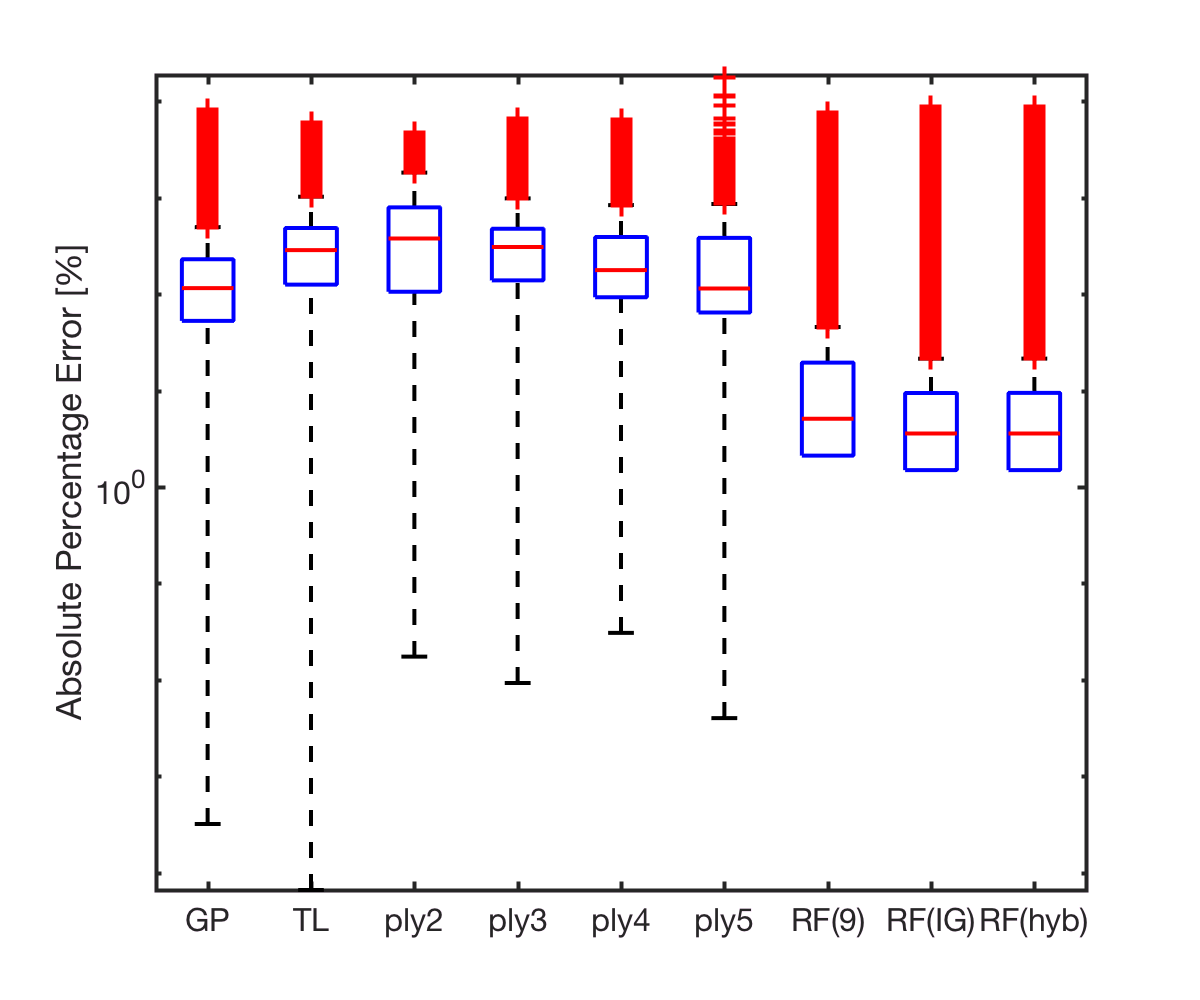

fontset


idx=2;
labels={'GP','TL','ply2','ply3','ply4','ply5','RF(9)','RF(IG)','RF(hyb)'};
errorData=[gpAEs(:,1),gpAEs(:,2),polyAE(:,2),polyAE(:,3),polyAE(:,4),polyAE(:,5),rfAEs(:,1),rfAEs(:,2),rfAEs(:,3)];
boxplot(errorData,'Labels',labels);
set(gca, 'YScale', 'log')
ylabel('Absolute Error [m]')

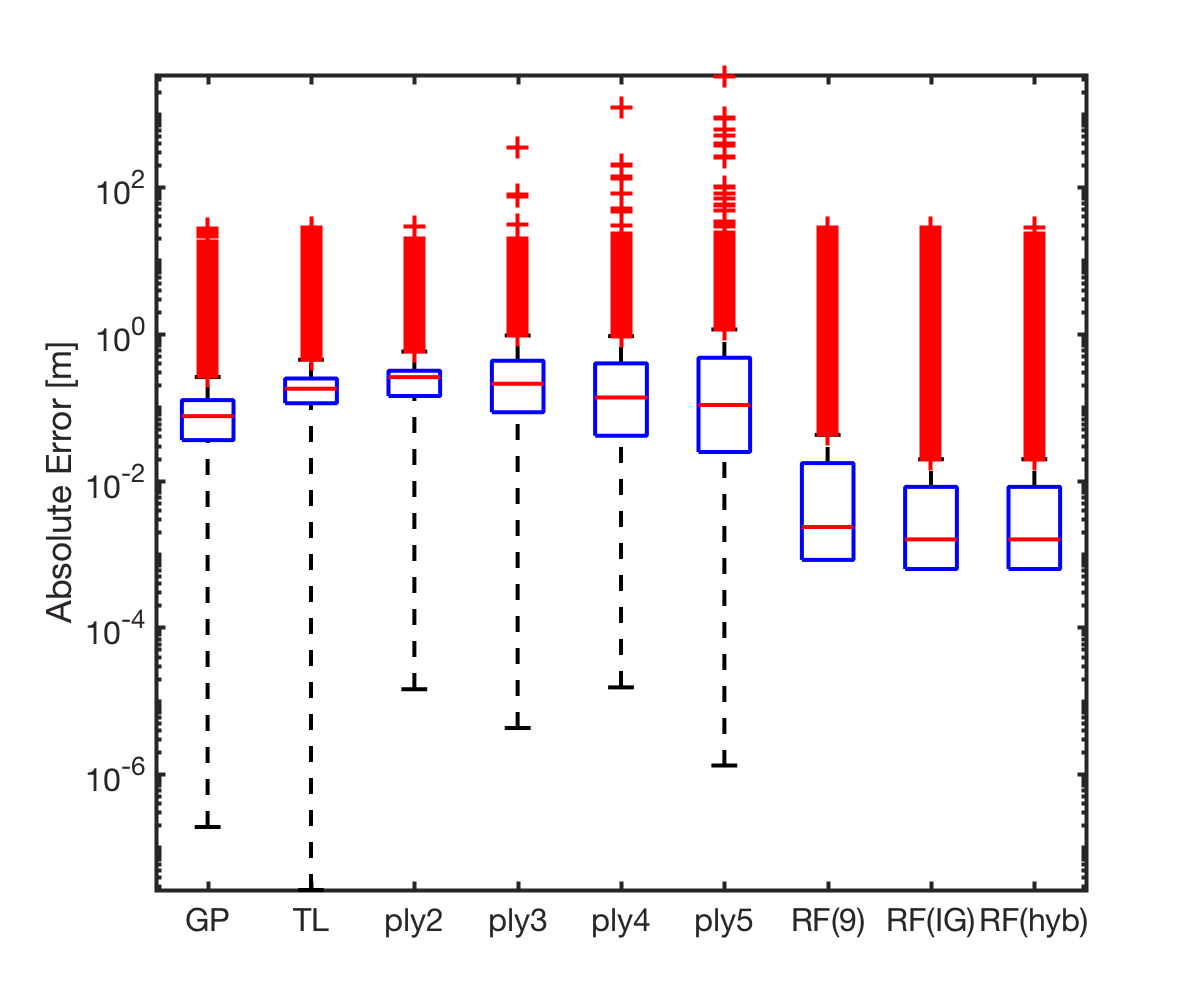

fontset


idx=2;
labels={'GP','TL','ply2','ply3','ply4','ply5','RF(9)','RF(IG)','RF(hyb)'};
errorData=[gpAPs(idx_test,1),gpAPs(idx_test,2),polyAP(idx_test,2),polyAP(idx_test,3),polyAP(idx_test,4),polyAP(idx_test,5),rfAPs(idx_test,1),rfAPs(idx_test,2),rfAPs(idx_test,3)];
boxplot(errorData,'Labels',labels);
set(gca, 'YScale', 'log')
ylabel('Absolute Percentage Error [%]')

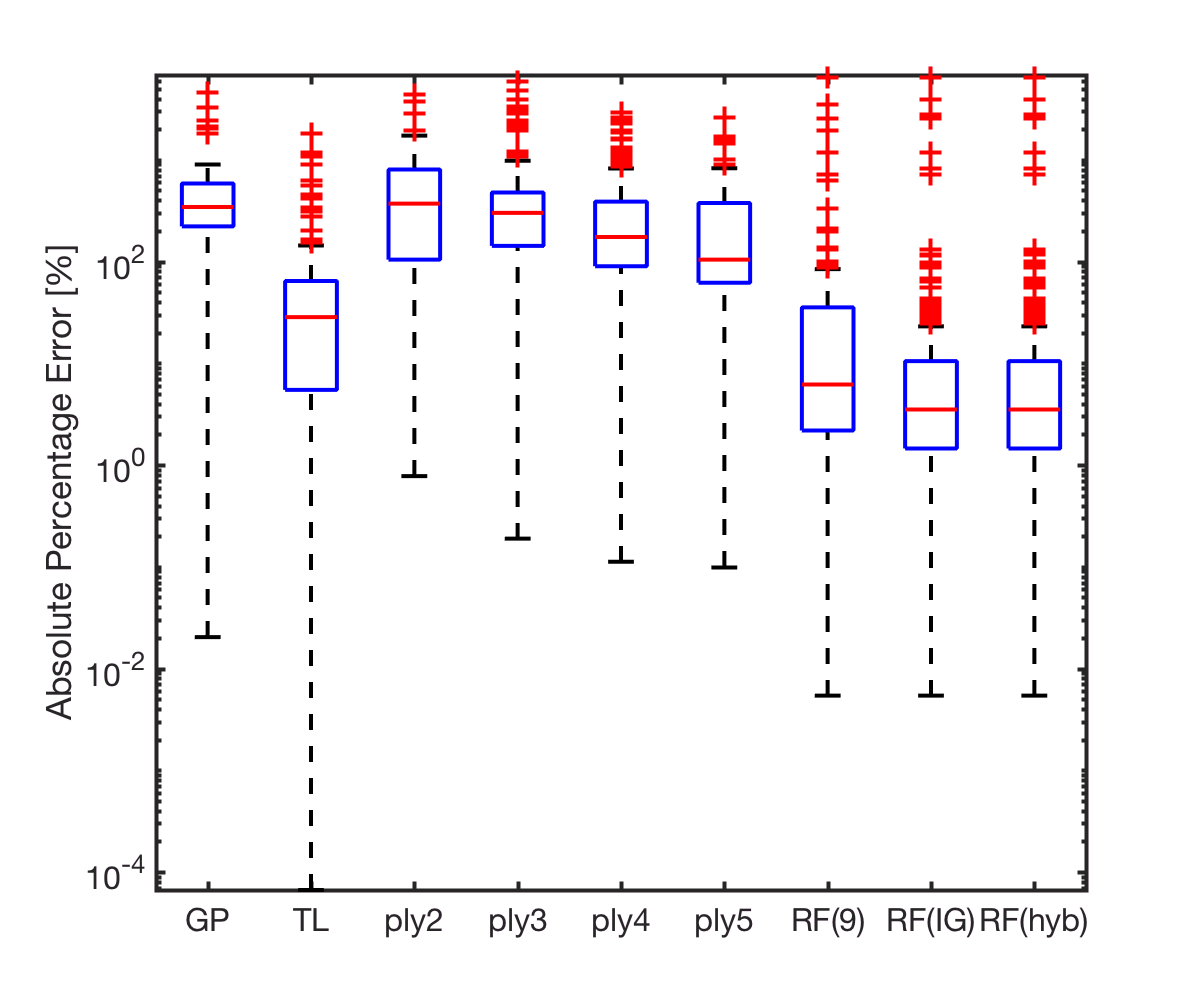

fontset


idx=2;
labels={'GP','TL','ply2','ply3','ply4','ply5','RF(9)','RF(IG)','RF(hyb)'};
errorData=[gpAEs(idx_test,1),gpAEs(idx_test,2),polyAE(idx_test,2),polyAE(idx_test,3),polyAE(idx_test,4),polyAE(idx_test,5),rfAEs(idx_test,1),rfAEs(idx_test,2),rfAEs(idx_test,3)];
boxplot(errorData,'Labels',labels);
set(gca, 'YScale', 'log')
ylabel('Absolute Error [m]')

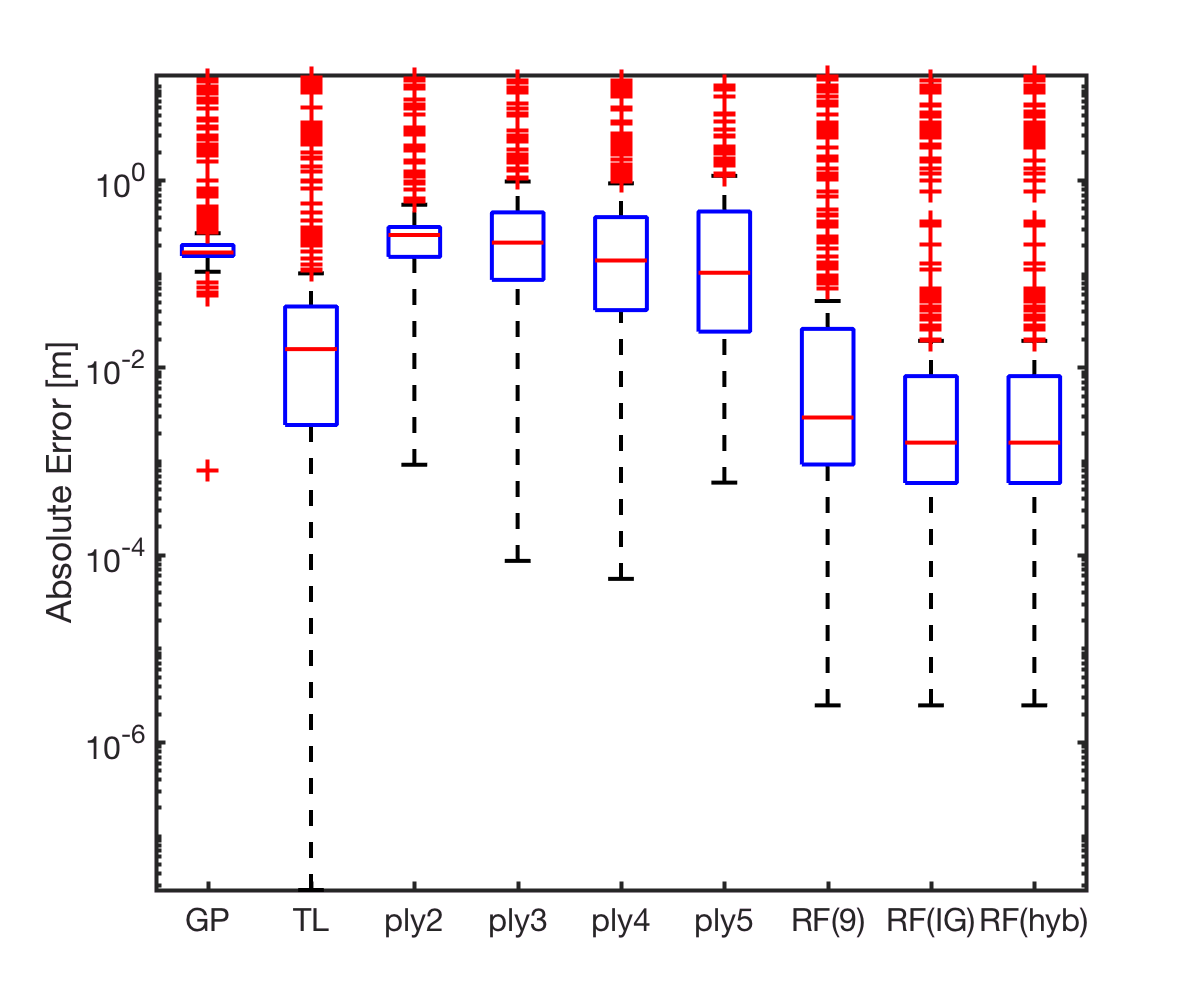

fontset

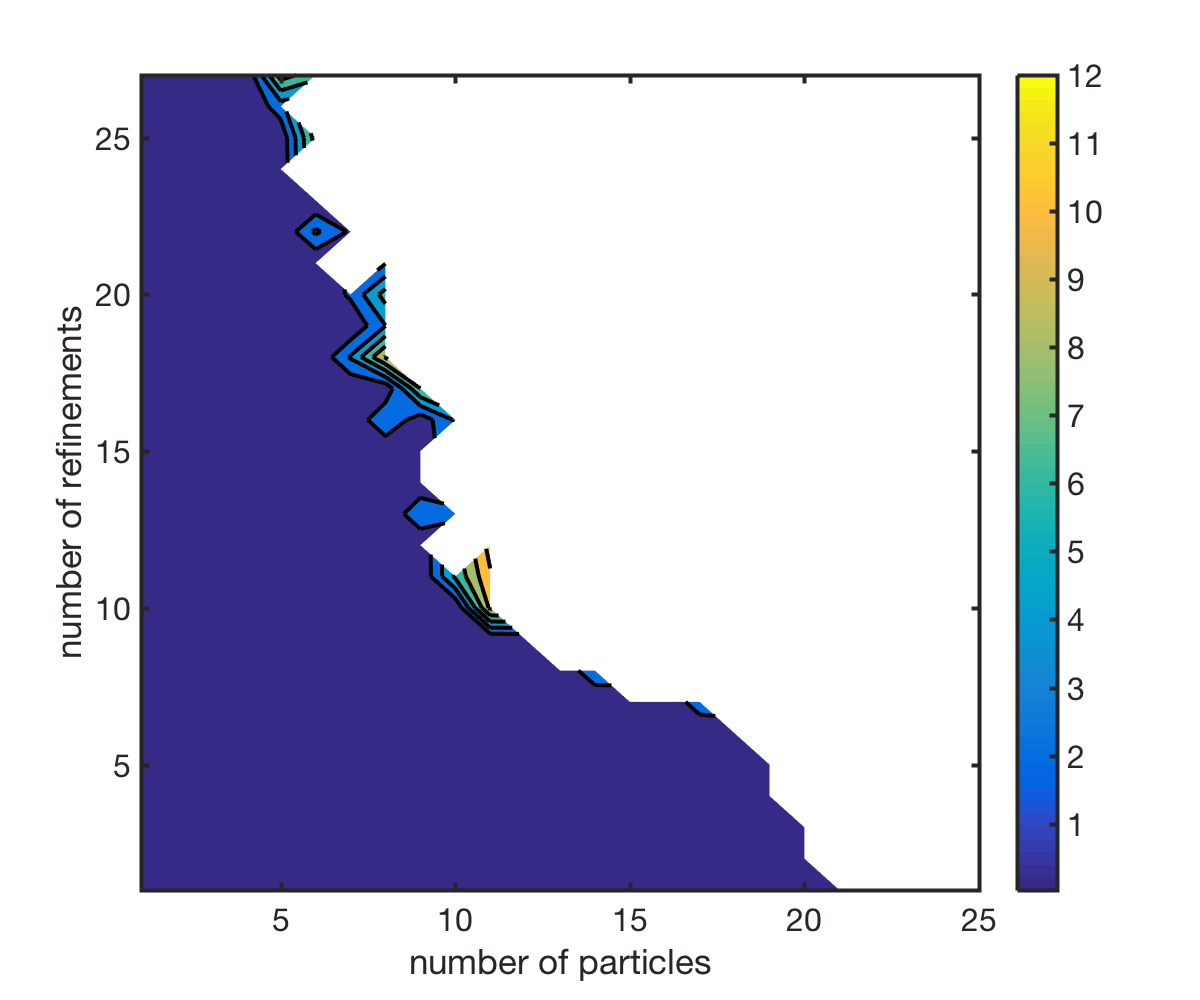



[X,Y]=meshgrid([5,10,20,30,40,50,70,100,125,150,200,250,300,350,400,450,500,750,1000,1500,2000,3500,5000,7500,10000],[1,3,5,8,10,15,20,35,50,70,100,150,200,250,300,350,400,450,500,750,1000,1500,2000,3500,5000,7500,10000]);

%yTest
for i=1:size(X,1)
for j=1:size(X,2)
    avErr(i,j)=mean(yTest(find(xTest(:,1)==0.35 & xTest(:,2)==0.45 & xTest(:,3)==X(i,j) & xTest(:,4)==Y(i,j))));
end
end
%surf(X,Y,avErr)
contourf(avErr)
colorbar
xlabel('number of particles')
ylabel('number of refinements')
fontset

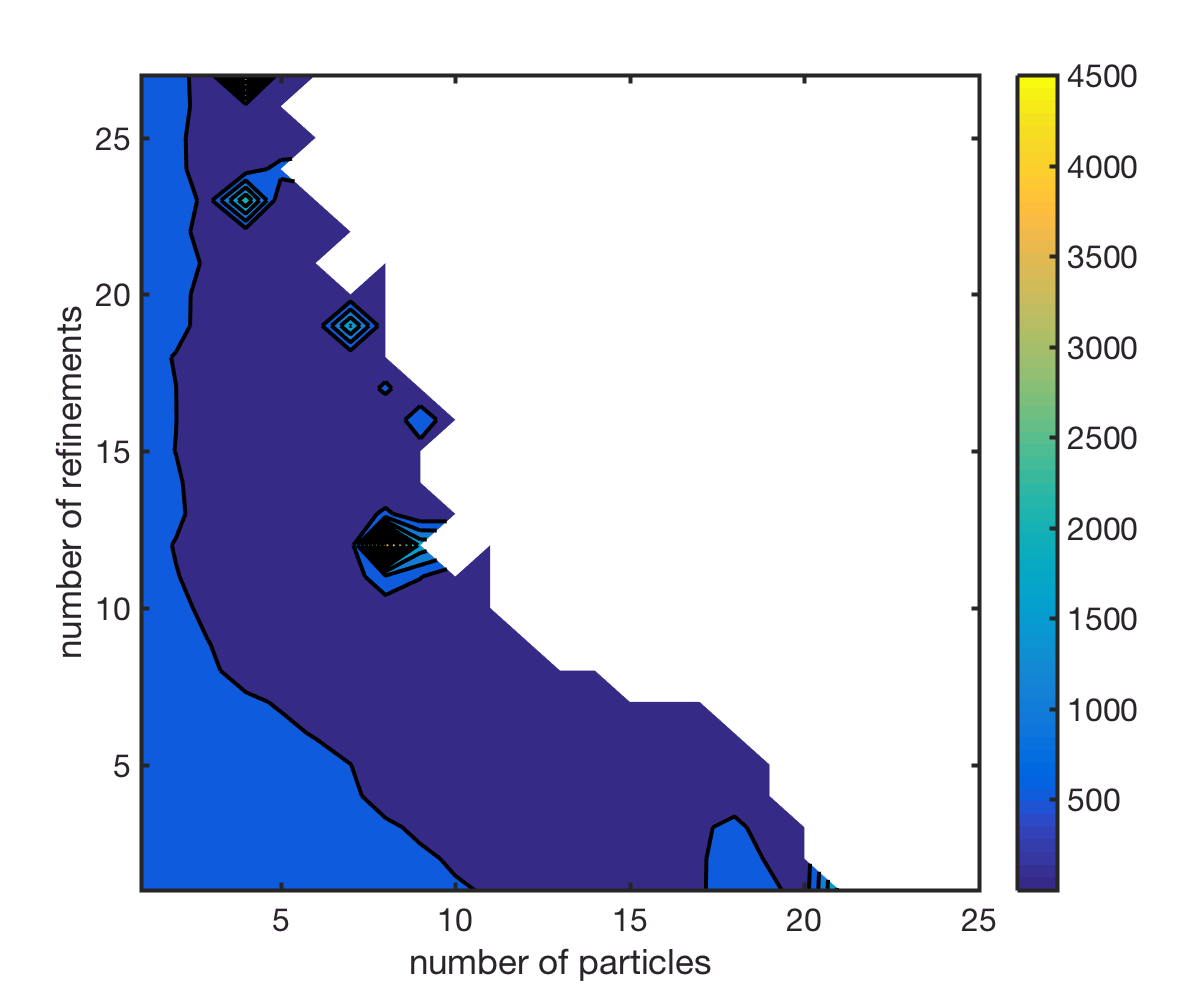



%GP
t=1;
for i=1:size(X,1)
for j=1:size(X,2)
    avErr(i,j)=mean(gpAPs(find(xTest(:,1)==0.35 & xTest(:,2)==0.45 & xTest(:,3)==X(i,j) & xTest(:,4)==Y(i,j)),t));
end
end
%surf(X,Y,avErr)
contourf(avErr)
colorbar
xlabel('number of particles')
ylabel('number of refinements')
fontset

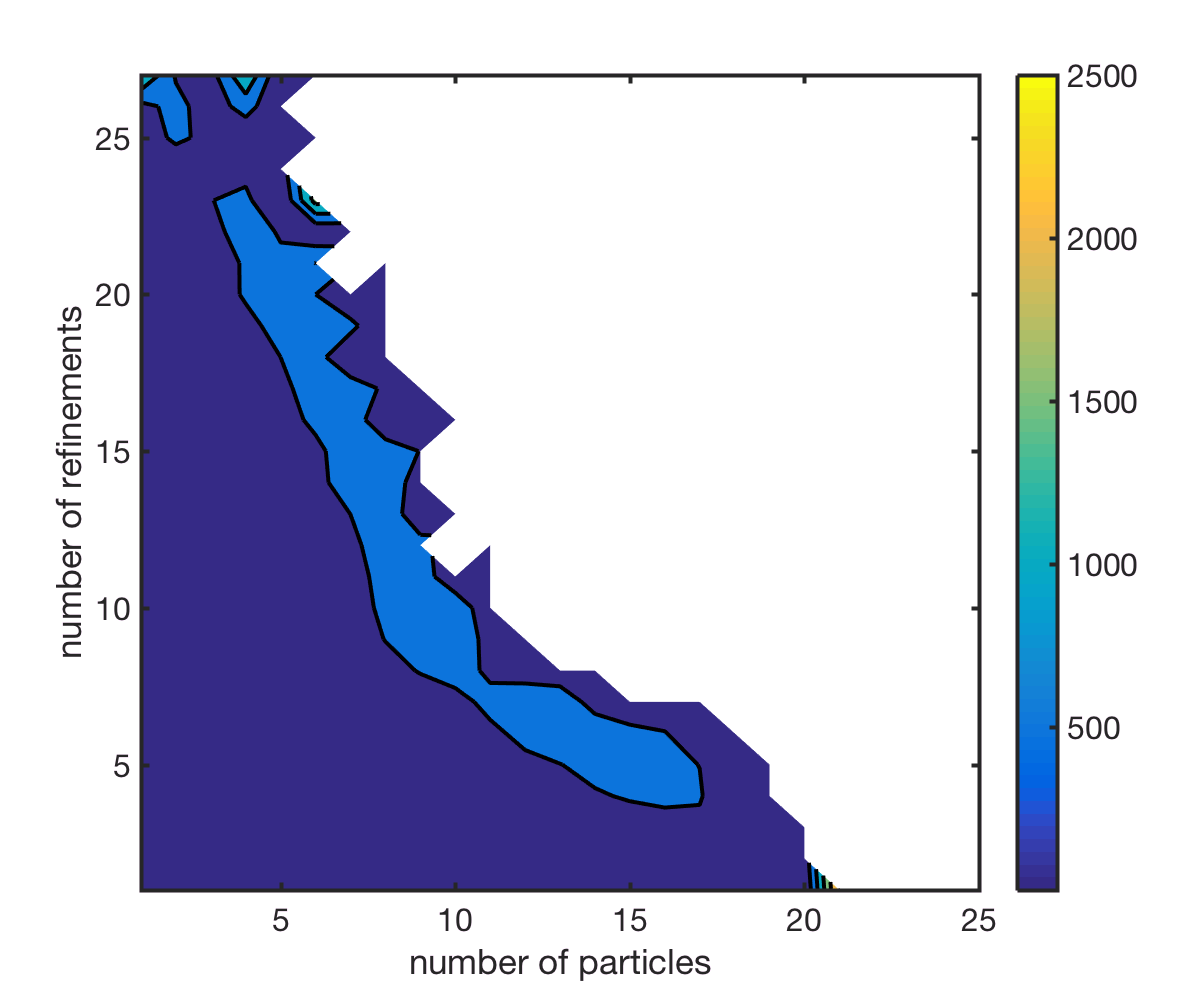


%poly
d=5;
for i=1:size(X,1)
for j=1:size(X,2)
    avErr(i,j)=mean(polyAP(find(xTest(:,1)==0.35 & xTest(:,2)==0.45 & xTest(:,3)==X(i,j) & xTest(:,4)==Y(i,j)),d));
end
end
%surf(X,Y,avErr)
contourf(avErr)
colorbar
xlabel('number of particles')
ylabel('number of refinements')
fontset

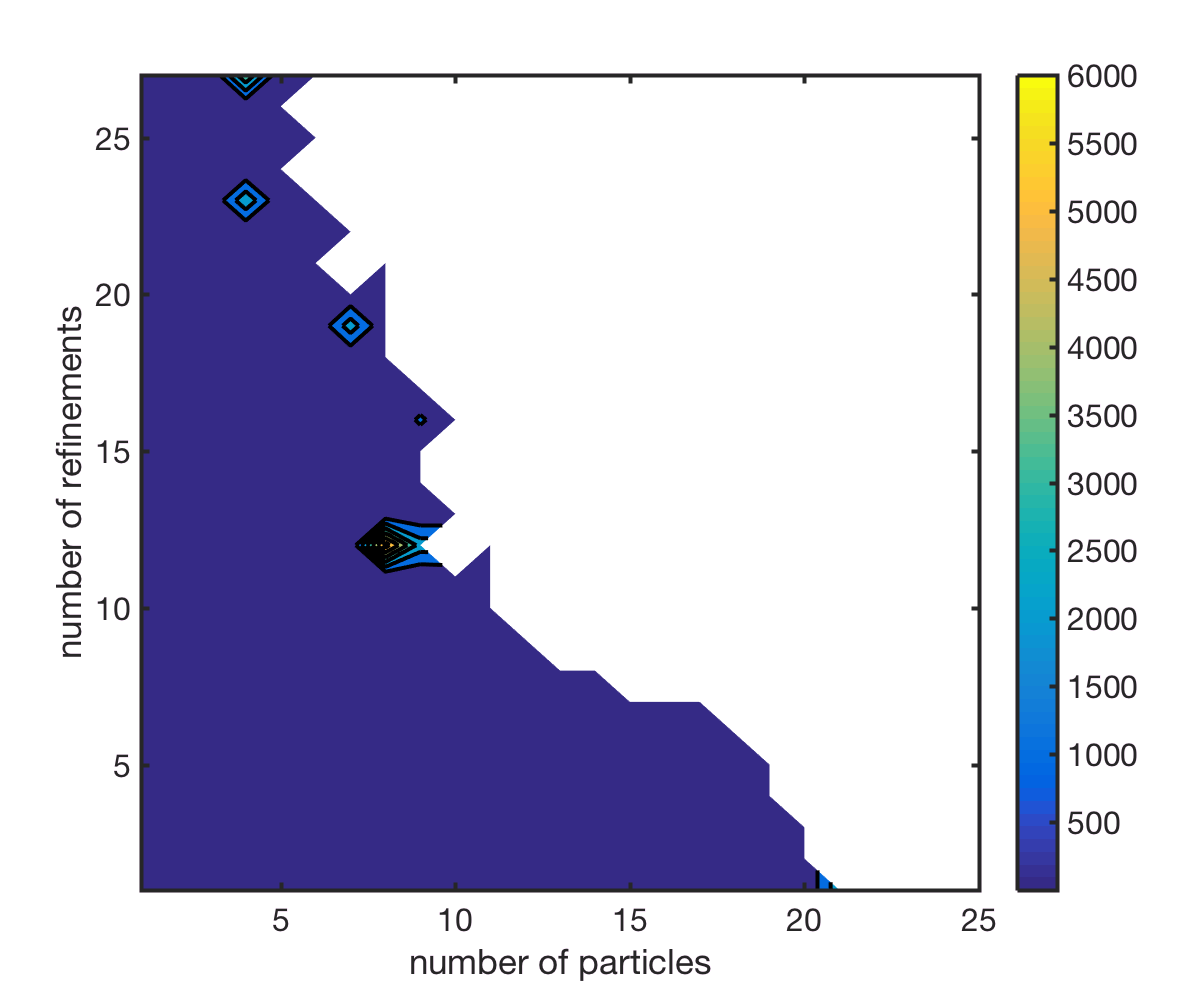


%rf
l=3;
for i=1:size(X,1)
for j=1:size(X,2)
    avErr(i,j)=mean(rfAPs(find(xTest(:,1)==0.35 & xTest(:,2)==0.45 & xTest(:,3)==X(i,j) & xTest(:,4)==Y(i,j)),l));
end
end
%surf(X,Y,avErr)
contourf(avErr)
colorbar
xlabel('number of particles')
ylabel('number of refinements')
fontset

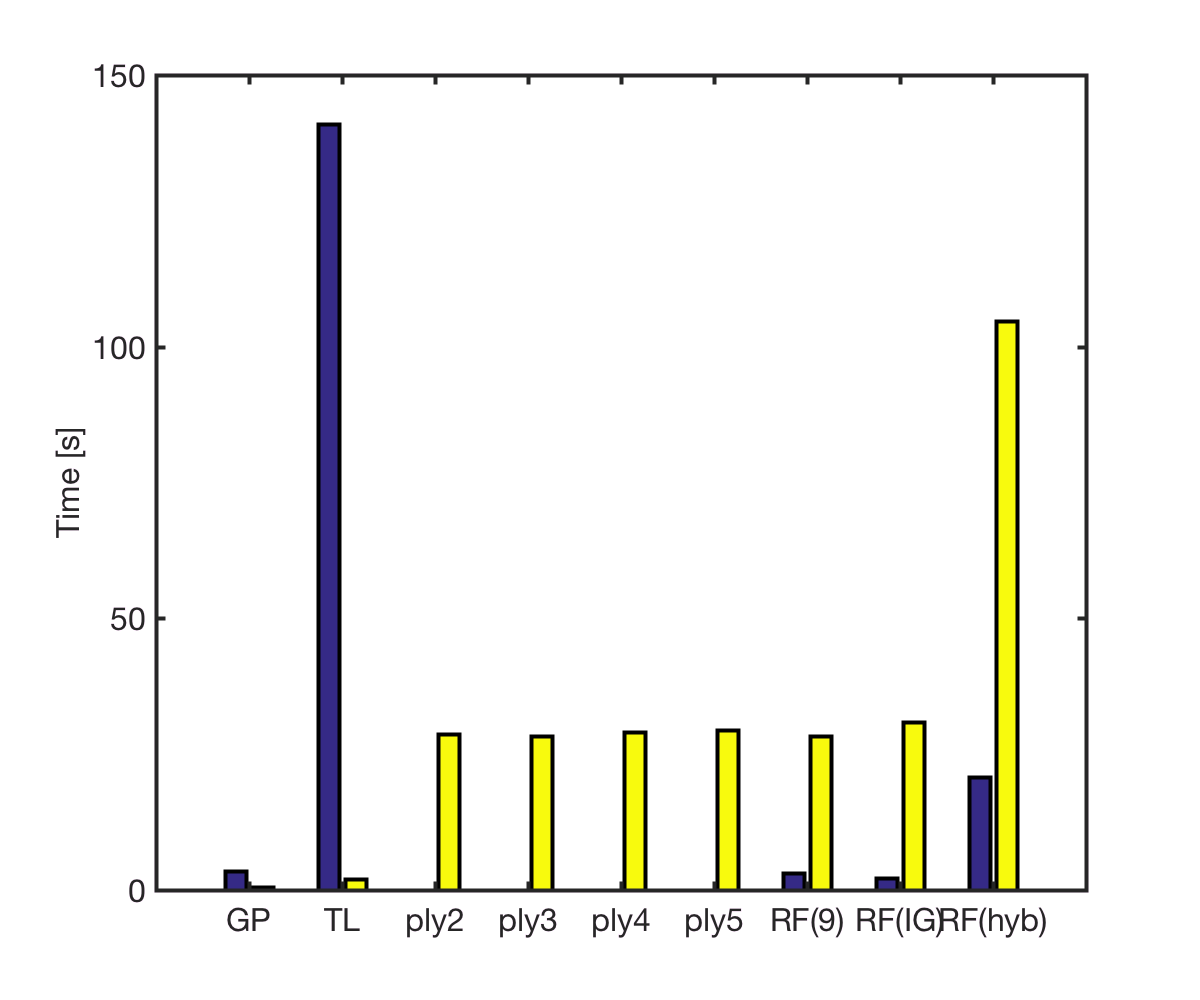


% overhead
timetrain_all=[timetrain_gp,timetrain_mtgp,timetrain_poly(2:end),timetrain_rf];
timetest_all=[timetest_gp,timetest_mtgp,timetest_poly(2:end),timetest_rf];
timetraintest_all=[timetrain_all;timetest_all];
bar(timetraintest_all');
set(gca, 'XTickLabel', labels);
ylabel('Time [s]')
fontset